clear;
close all;
clc;
format compact;

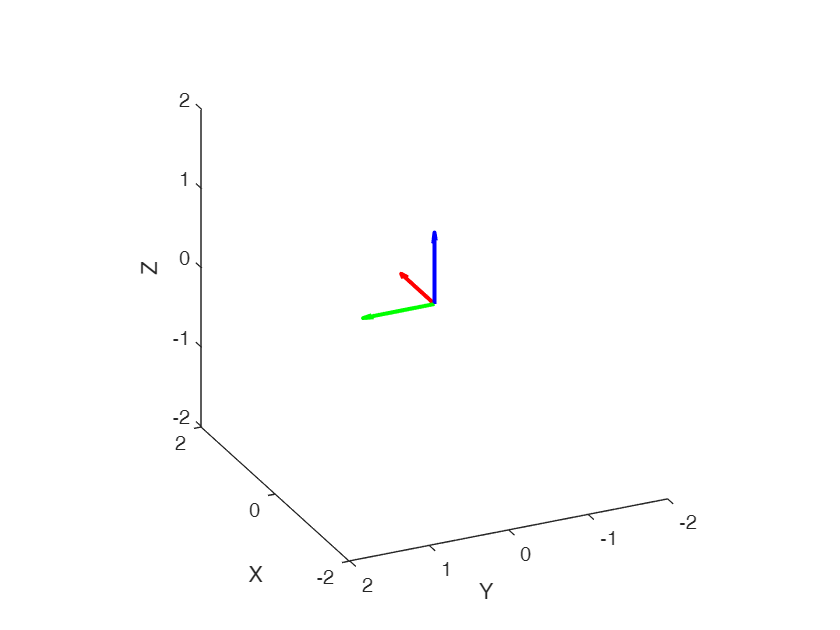

% 3D vectors
figure;
ax = draw3DFrame([1 0 0; 0 1 0; 0 0 1], [0, 0, 0], 'scale', 1);
xlabel( 'X' ); ylabel( 'Y' ); zlabel( 'Z' );
axis equal;
xlim(1*[-2 2])
ylim(1*[-2 2])
zlim(1*[-2 2])
view([-115 25])

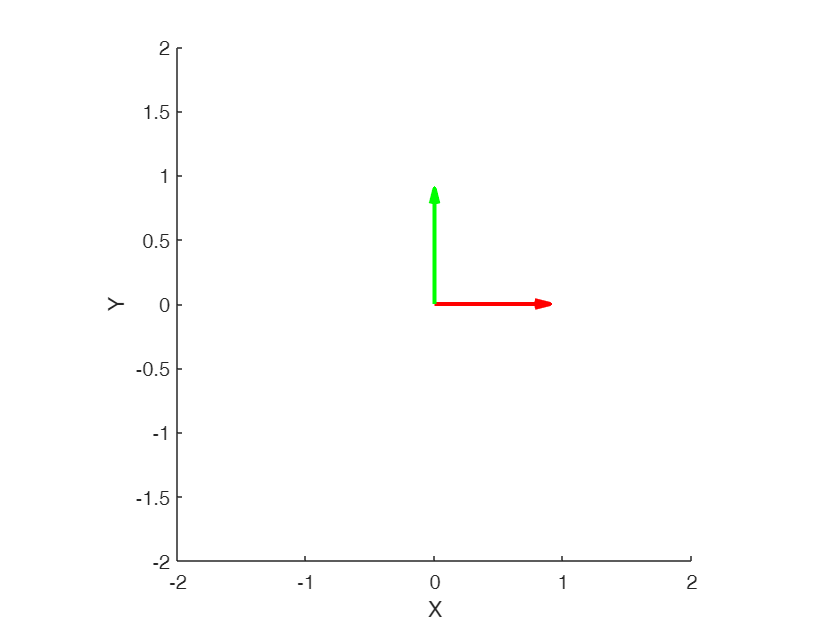

rotationMatrix = [ 1 0;0 1];  % 90 degrees rotation
translationVector = [0, 0];
figure;
plot2DFrame(rotationMatrix, translationVector);
xlabel( 'X' ); ylabel( 'Y' );
axis equal;
xlim(1*[-2 2])
ylim(1*[-2 2])

function varargout = draw3DFrame(varargin)
% PLOTFRAME Plot a 3-D Cartesian coordinate system.
%
%   plotframe() 
%   plotframe(rotationMatrix, translationVector) 
%   plotframe(rotationMatrix, translationVector, 'Scale', 2, 'LineWidth', 3)
%
%   Name-Value Pair Arguments:
%   - 'Rotation': 3x3 orthogonal matrix defining orientation (default: eye(3))
%   - 'Translation': 1x3 vector defining position (default: [0, 0, 0])
%   - 'Scale': Scalar or 1x3 vector defining basis vector lengths (default: 1)
%   - 'LineWidth': Line width for the quiver plot (default: 2)
%   - 'Color': Cell array of colors for each axis (default: {'r', 'g', 'b'})

    % Define default values
    defaultRotation = eye(3);
    defaultTranslation = [0, 0, 0];
    defaultScale = 1;
    defaultLineWidth = 2;
    defaultColor = {'r', 'g', 'b'};

    % Initialize rotationMatrix and translationVector with default values
    rotationMatrix = defaultRotation;
    translationVector = defaultTranslation;

    % Check if the first argument is a rotation matrix
    if nargin >= 1 && isnumeric(varargin{1}) && isequal(size(varargin{1}), [3, 3])
        rotationMatrix = varargin{1};
        varargin(1) = []; % Remove first positional argument
    end

    % Check if the second argument is a translation vector
    if nargin >= 1 && isnumeric(varargin{1}) && numel(varargin{1}) == 3
        translationVector = varargin{1};
        varargin(1) = []; % Remove second positional argument
    end

    % Parse name-value pair arguments
    parser = inputParser;
    addParameter(parser, 'Scale', defaultScale, @(x) isscalar(x) || (isvector(x) && length(x) == 3));
    addParameter(parser, 'LineWidth', defaultLineWidth, @isscalar);
    addParameter(parser, 'Color', defaultColor, @(x) iscell(x) && length(x) == 3);

    parse(parser, varargin{:});

    % Extract parsed values
    scale = parser.Results.Scale;
    lineWidth = parser.Results.LineWidth;
    colors = parser.Results.Color;

    % Ensure scale is a 1x3 vector
    if isscalar(scale)
        scale = [scale, scale, scale];
    end

    % Compute basis vectors
    basisVectors = rotationMatrix .* scale;

    % Create quiver plot for each axis
    hold on;
    for i = 1:3
        quiver3(translationVector(1), translationVector(2), translationVector(3), ...
            basisVectors(1, i), basisVectors(2, i), basisVectors(3, i), ...
            'Color', colors{i}, 'LineWidth', lineWidth, 'MaxHeadSize', 0.4);
    end
    hold off;

    % Output the plot handle if requested
    if nargout > 0
        varargout = {gca};
    end
end

function varargout = plot2DFrame(varargin)
% PLOT2DFRAME Plot a 2-D Cartesian coordinate system.
%
%   plot2DFrame() 
%   plot2DFrame(rotationMatrix, translationVector) 
%   plot2DFrame(rotationMatrix, translationVector, 'Scale', 2, 'LineWidth', 3)
%
%   Name-Value Pair Arguments:
%   - 'Rotation': 2x2 orthogonal matrix defining orientation (default: eye(2))
%   - 'Translation': 1x2 vector defining position (default: [0, 0])
%   - 'Scale': Scalar or 1x2 vector defining basis vector lengths (default: 1)
%   - 'LineWidth': Line width for the quiver plot (default: 2)
%   - 'Color': Cell array of colors for each axis (default: {'r', 'g'})
%
%   OUTPUT:
%   - If requested, returns the handle of the current axes (gca).

    % Define default values for optional arguments
    defaultRotation = eye(2);         % Default rotation matrix (identity matrix)
    defaultTranslation = [0, 0];     % Default translation vector (origin)
    defaultScale = 1;                 % Default scale for basis vectors
    defaultLineWidth = 2;             % Default line width for quiver plot
    defaultColor = {'r', 'g'};        % Default colors for the x and y axes

    % Initialize rotationMatrix and translationVector with default values
    rotationMatrix = defaultRotation;
    translationVector = defaultTranslation;

    % Check if the first argument is a rotation matrix
    if nargin >= 1 && isnumeric(varargin{1}) && isequal(size(varargin{1}), [2, 2])
        rotationMatrix = varargin{1}; % Assign rotation matrix
        varargin(1) = [];              % Remove the first argument from varargin
    end

    % Check if the second argument is a translation vector
    if nargin >= 1 && isnumeric(varargin{1}) && numel(varargin{1}) == 2
        translationVector = varargin{1}; % Assign translation vector
        varargin(1) = [];                % Remove the second argument from varargin
    end

    % Create an input parser object to handle name-value pair arguments
    parser = inputParser;
    addParameter(parser, 'Scale', defaultScale, @(x) isscalar(x) || (isvector(x) && length(x) == 2));
    addParameter(parser, 'LineWidth', defaultLineWidth, @isscalar);
    addParameter(parser, 'Color', defaultColor, @(x) iscell(x) && length(x) == 2);

    % Parse the remaining name-value pair arguments
    parse(parser, varargin{:});

    % Extract parsed values from the parser results
    scale = parser.Results.Scale;
    lineWidth = parser.Results.LineWidth;
    colors = parser.Results.Color;

    % Ensure scale is a 1x2 vector
    if isscalar(scale)
        scale = [scale, scale]; % Convert scalar to a 1x2 vector
    end

    % Compute basis vectors by scaling the rotation matrix
    basisVectors = rotationMatrix .* scale;

    % Create a 2D quiver plot for each axis
    hold on; % Keep the current plot
    for i = 1:2
        % Plot each axis with the specified color and line width
        quiver(translationVector(1), translationVector(2), ...
               basisVectors(1, i), basisVectors(2, i), ...
               'Color', colors{i}, 'LineWidth', lineWidth, 'MaxHeadSize', 0.4);
    end
    hold off; % Release the current plot

    % Output the plot handle if requested
    if nargout > 0
        varargout = {gca}; % Return the handle to the current axes
    end
end